# パイプ内の熱伝達 

## 伝熱モデルの構築 

PDEオブジェクトを、thermalモードで構築します。

model = createpde('thermal');

## 形状の作成

PDEオブジェクトに解きたい形状情報を与えます。ここではmulti cylinderを使い、外側と内側でセルを分けておきます。

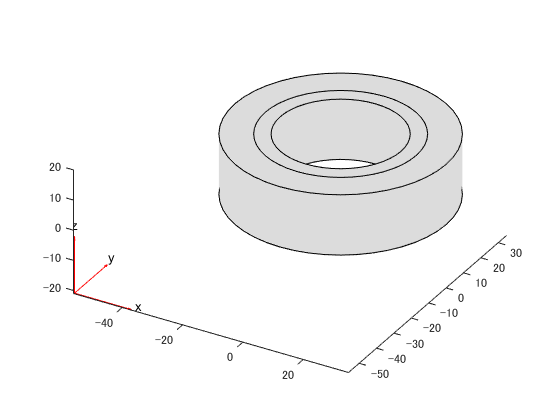

geom = multicylinder([20,25,35],20,'Void',[1,0,0]);
model.Geometry = geom;
pdegplot(model);

## メッシュの構築

内部の詰まった、四面体メッシュデータを作成します。メッシュ精度は変更可能ですが、今回はデフォルト値を使用します。

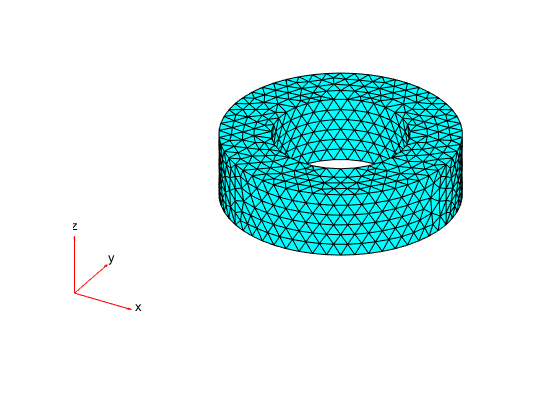

generateMesh(model);
pdemesh(model);

# 多媒質のパイプにおける熱伝達

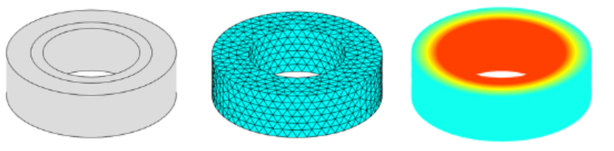

## MATLABにおける有限要素法のワークフロ

以下では、内側と外側に異なる物性値や初期温度を与えることで、シミュレーション結果がどのように変化するかを確認します。7行目8行目ではLive Scriptの機能である、タスクを使っています。

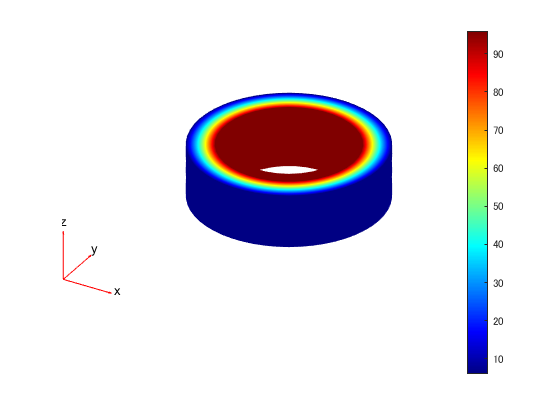

T1 =96;
T2 = 6;

thermalProperties(model,'cell',1,'ThermalConductivity',40);
thermalProperties(model,'cell',2,'ThermalConductivity',0.15);

thermalBC(model,'Face',3,'Temperature',T1);
thermalBC(model,'Face',7,'Temperature',T2);

results = solve(model);
pdeplot3D(model,'ColorMapData',results.Temperature)

Copyright 2018-2020 The MathWorks, Inc.

*translation: Dr. Hiroyuki HISHIDA*